# Aerial Image Semantic Segmentation Using Deep Learning [UNet | SegNet | DeepLabv3+]

## Load  Images

Display one of the images.

imgDir = fullfile('outImageFolder');
imds = imageDatastore(imgDir);
figure
montage(imds)

## Define Dataset Pixel-Labeled Images

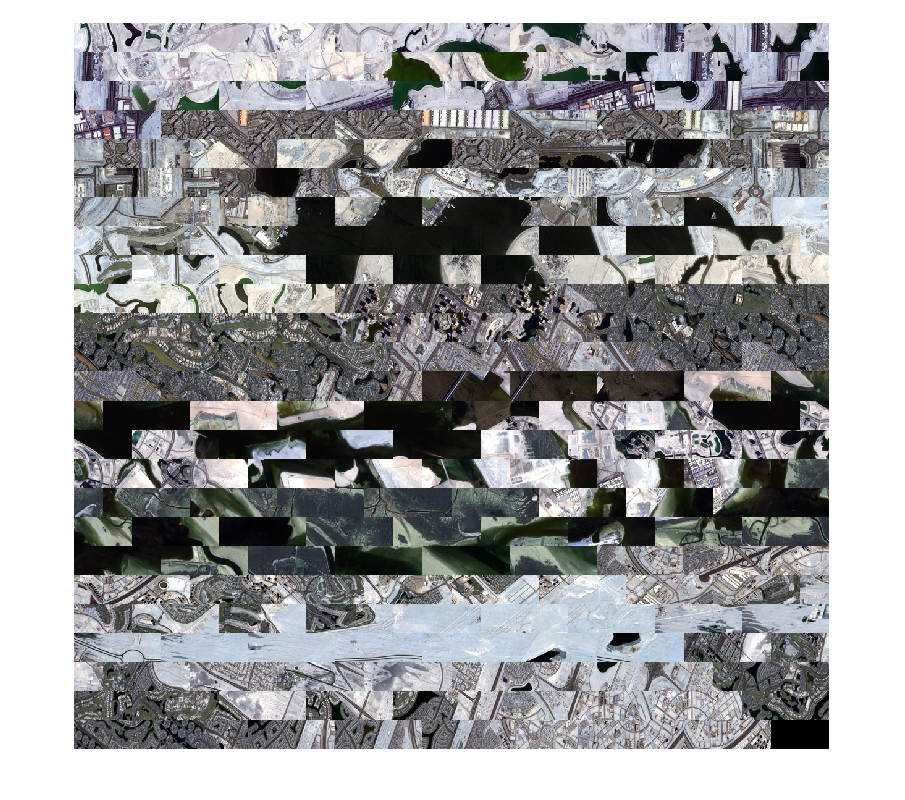

classes = [
    "Building"
    "Land_UnpavedArea"
    "Road"

    "Vegetation"
    "Water"
    "Unlabeled"
    ];

% Building: #3C1098
% Land (unpaved area): #8429F6
% Road: #6EC1E4
% Vegetation: #FEDD3A
% Water: #E2A929
% Unlabeled: #9B9B9B

### `PixelLabelIDs`

labelIDs = camvidPixelLabelIDs();
cmap = camvidColorMap;

Use the classes and label IDs to create the `pixelLabelDatastore.`

labelDir = fullfile('outMaskFolder');
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

Read and display one of the pixel-labeled images by overlaying it on top of an image.

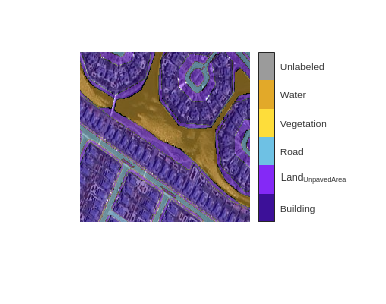

I = readimage(imds,311);
C = readimage(pxds,311);
cmap = camvidColorMap;
B = labeloverlay(I,C,'ColorMap',cmap,'Transparency',0.5);
imshow(B)
pixelLabelColorbar(cmap,classes);

## Analyze Dataset Statistics

tbl = countEachLabel(pxds)

tbl = 6×3 table
            Name            PixelCount    ImagePixelCount
    ____________________    __________    _______________

    {'Building'        }    3.5554e+06      1.8214e+07   
    {'Land_UnpavedArea'}    1.4646e+07      3.0156e+07   
    {'Road'            }    2.4321e+06      2.3834e+07   
    {'Vegetation'      }    3.0031e+06      1.7361e+07   
    {'Water'           }    6.7353e+06      2.0371e+07   
    {'Unlabeled'       }    2.7214e+05      7.7773e+06   


Visualize the pixel counts by class.

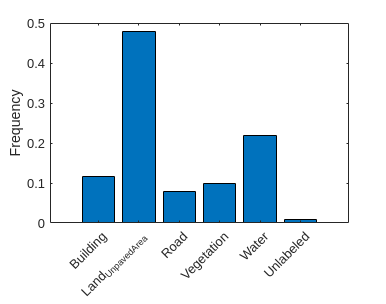

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

## Prepare Training, Validation, and Test Sets

[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds);

The 60/20/20 split results in the following number of training, validation and test images:

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 389

numValImages = numel(imdsVal.Files)

numValImages = 130

numTestingImages = numel(imdsTest.Files)

numTestingImages = 129

## Create the Network

% Specify the network image size. This is typically the same as the traing image sizes.
imageSize = [224 224 3];

% Specify the number of classes.
numClasses = numel(classes);


### **1. Create DeepLab v3+.**

*To be commented when training the other models *

resnet18()

ans =   DAGNetwork with properties:

         Layers: [71×1 nnet.cnn.layer.Layer]
    Connections: [78×2 table]
     InputNames: {'data'}
    OutputNames: {'ClassificationLayer_predictions'}


lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet18");

### **2. Create UNet **

*To be uncommented when training the model *

% lgraph = unetLayers(imageSize, numClasses)

### **3. Create SegNet**

*To be uncommented when training the model *

% lgraph = segnetLayers(imageSize,numClasses,3)

## Balance Classes Using Class Weighting

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.9431
    0.3790
    1.8040
    1.0642
    0.5568
    5.2610


Specify the class weights using a [ `pixelClassificationLayer`](docid:vision_ref.mw_783aebd8-1ff1-4bc6-8508-90c8b71fca32). for DeepLabv3+

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

## Select Training Options

The optimization algorithm used for training is stochastic gradient descent with momentum (SGDM). Use [`trainingOptions`](docid:nnet_ref.bu59f0q) to specify the hyper-parameters used for SGDM.

% Define validation data.
dsVal = combine(imdsVal,pxdsVal);

% Define training options. 
options = trainingOptions('adam', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',dsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',4, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', tempdir, ...
    'VerboseFrequency',2,...
    'Plots','training-progress');


## Data for Training

dsTrain = combine(imdsTrain, pxdsTrain);

## Start Training

*Uncomment for traning the network*

% uncomment for traning the network
% doTraining = false;
% if doTraining    
    % [net, info] = trainNetwork(dsTrain,lgraph,options);
% end

## Test Network on One Image

As a quick sanity check, run the trained network on one test image. 

I = readimage(imdsTrain,5);
C = semanticseg(I, net);

Display the results.

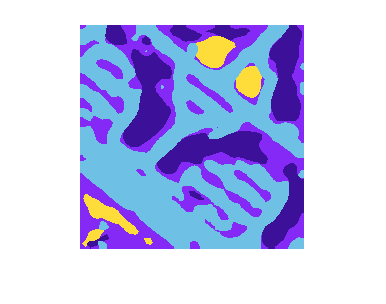

B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0);
imshow(B)

Compare the results in `C` with the expected ground truth stored in `pxdsTest`. 

The green and magenta regions highlight areas where the segmentation results differ from the expected ground truth.

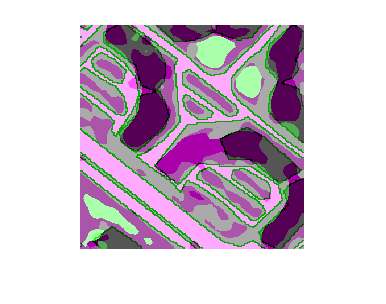

expectedResult = readimage(pxdsTrain,5);
actual = uint8(C);
expected = uint8(expectedResult);
imshowpair(actual, expected)

Visually, the semantic segmentation results overlap well for classes s

iou = jaccard(C,expectedResult);
table(classes,iou)

ans = 6×2 table
         classes            iou  
    __________________    _______

    "Building"            0.56742
    "Land_UnpavedArea"    0.31836
    "Road"                0.38947
    "Vegetation"                0
    "Water"                   NaN
    "Unlabeled"               NaN


## Evaluate Trained Network

% the argument to semanticseg can be changes to imdsTrain or imdsVal to
% evaluate the models perfomance on Train and Val Datasets


pxdsResults = semanticseg(imdsTest,net, ...
    'MiniBatchSize',4, ...
    'WriteLocation',tempdir, ...
    'Verbose',false);

% the argument to evaluateSemanticSegmentation can be changes to pxdsTrain or pxdsVal to
% evaluate the models perfomance on Train and Val Datasets


## for Entire Dataset


metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);

To see the dataset level metrics, inspect `metrics.DataSetMetrics` .

metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.80299          0.65954       0.52761      0.68825        0.60174  


## for Per-Class Metrics

To see the impact each class has on the overall performance, inspect the per-class metrics using `metrics.ClassMetrics`.

metrics.ClassMetrics

ans = 6×3 table
                        Accuracy       IoU       MeanBFScore
                        _________    ________    ___________

    Building              0.85111     0.61704      0.60694  
    Land_UnpavedArea      0.79715     0.72875      0.57423  
    Road                  0.71323     0.41253      0.59105  
    Vegetation            0.66856     0.54006      0.38595  
    Water                 0.92558     0.86582      0.66814  
    Unlabeled           0.0015848    0.001486     0.024964  


## Supporting Functions

function labelIDs = camvidPixelLabelIDs()

labelIDs = { ...
    
    % "Building"
    [
    60 16 152; ... % "Building"
    ]
    
    % "Land (Unpaved Area)"
    [
    132 41 246; ... % "Land (Unpaved Area)"
    ]

    % "Road"
    [
    110 193 228; ... % "Road"
    ]
    
    % "Vegetation"
    [
    254 221 58; ... % "Vegetation"
    ]

    % "Water"
    [
    226 169 41; ... % "Water"
    ]
    
    % "Unlabeled"
    [
    155 155 155; ... % "Unlabeled"
    ]
    };
end

% Building: #3C1098
% Land (unpaved area): #8429F6
% Road: #6EC1E4
% Vegetation: #FEDD3A
% Water: #E2A929
% Unlabeled: #9B9B9B


function pixelLabelColorbar(cmap, classNames)
colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classNames;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end

function cmap = camvidColorMap()

cmap = [
    60 16 152   % "Building"
    132 41 246  % "Land (Unpaved Area)"
    110 193 228 % "Road"
    254 221 58  % "Vegetation"
    226 169 41  % "Water"
    155 155 155 % "Unlabeled"
    ];

% Normalize between [0 1].
cmap = cmap ./ 255;
end

function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds)
% Partition data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = camvidPixelLabelIDs();

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end